# Fast Fourier Transform (fft)

- y = fft(x) computes the discrete Fourier transform (DFT) of x using a fast Fourier transform (FFT) algorithm. 

- ifft(y) denotes the inverse fast Fourier transform of y, and retrives x.

- Both fft and ifft use the same syntax, we shall discuss only the syntax of fft. As shown below.

## Usage,  y = fft(x)

- If x is a vector, then fft(x) returns the Fourier transform of the vector

- If x is a matrix, then fft(x) treats the column of x as vectors and returns the Fourier transform of each column.

- If x is a multidimensional array, then fft(x) treats the values along the first array dimension whose size does not equal 1 as vectors and returns the Fourier transform of each vector.

%%Examples
% when x is a vector
xvec = [1:0.2:4]'

xvec =     1.0000
    1.2000
    1.4000
    1.6000
    1.8000
    2.0000
    2.2000
    2.4000
    2.6000
    2.8000



%fft(x)
y = fft(xvec)

y =   40.0000 + 0.0000i
  -1.6000 + 8.0437i
  -1.6000 + 3.8627i
  -1.6000 + 2.3946i
  -1.6000 + 1.6000i
  -1.6000 + 1.0691i
  -1.6000 + 0.6627i
  -1.6000 + 0.3183i
  -1.6000 + 0.0000i
  -1.6000 - 0.3183i



%ifft(y)
yi = ifft(y)

yi =     1.0000
    1.2000
    1.4000
    1.6000
    1.8000
    2.0000
    2.2000
    2.4000
    2.6000
    2.8000



% when x is a matrix
xmat = [1 2 3 4; 5 6 7 8; 9 10 2 3; 4 3 6 0]

xmat =      1     2     3     4
     5     6     7     8
     9    10     2     3
     4     3     6     0



%fft(x)
y = fft(xmat)

y =   19.0000 + 0.0000i  21.0000 + 0.0000i  18.0000 + 0.0000i  15.0000 + 0.0000i
  -8.0000 - 1.0000i  -8.0000 - 3.0000i   1.0000 - 1.0000i   1.0000 - 8.0000i
   1.0000 + 0.0000i   3.0000 + 0.0000i  -8.0000 + 0.0000i  -1.0000 + 0.0000i
  -8.0000 + 1.0000i  -8.0000 + 3.0000i   1.0000 + 1.0000i   1.0000 + 8.0000i



%ifft(y)
yi = ifft(y)

yi =      1     2     3     4
     5     6     7     8
     9    10     2     3
     4     3     6     0


## Usage, y = fft(x,n)

This returns  the n-point DFT. if no value is specified, but y and x must be of the same size.

- If x is a vector and the length of x is less than n, then x is padded with trailing zeros to length n.

- If x is a vector and the length of x is greater than n, then x is truncated to length n.

- if x is a matrix, then each column is treated as in the vector case.

- if x is a multidimensional array, then the first array dimension whose size does not equal 1 is treated as in the vector case.

%%Examples
% when x is a vector and length of x is less than n.
xvec = [1:0.5:4]';

%fft(x,n)
n = length(xvec) + 2

n = 9

y = fft(xvec,n)

y =   17.5000 + 0.0000i
  -6.8616 - 1.4637i
   1.1104 - 3.7817i
   2.5000 + 0.8660i
  -0.9987 + 1.5792i
  -0.9987 - 1.5792i
   2.5000 - 0.8660i
   1.1104 + 3.7817i
  -6.8616 + 1.4637i


%ifft(y,n)
yi = ifft(y,n)

yi =     1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000
    4.0000
   -0.0000
         0


length(y)

ans = 9


% when x is a vector and length of x is greater than n.
n = length(xvec) - 2

n = 5

y = fft(xvec,n)

y =   10.0000 + 0.0000i
  -1.2500 + 1.7205i
  -1.2500 + 0.4061i
  -1.2500 - 0.4061i
  -1.2500 - 1.7205i


%ifft(y,n)
yi = ifft(y,n)

yi =     1.0000
    1.5000
    2.0000
    2.5000
    3.0000


length(y)

ans = 5


% when x is a matrix
xmat = [1 2 3 4; 5 6 7 8; 9 10 2 3; 4 3 6 0];
%fft(x)
y = fft(xmat,n);
%ifft(y,n)
yi = ifft(y,n);

## Usage, y = fft(x,n,dim)

This returns the Fourier transform along the dimension dim. E.g, if x is a matrix, then fft(x,n,2) returns the n-point Fourier Transform of each row.

% when x is a matrix
xmat = [1 2 3 4; 5 6 7 8; 9 10 2 3; 4 3 6 0];
%fft(x)
y = fft(xmat,n,2);
%ifft(y,n,2)
yi = ifft(y,n,2);

## Example: Compute the fft of f(x) = sin(x) at 16 points

a = 0; b = 2*pi;
n = 16;

%n sample points
x = linspace(a,b,n+1);
x(end) = [];
%function f(x)
f = @ (x) sin(x);
f(x);

%fft of f(x)
y = fft(f(x))

y =   -0.0000 + 0.0000i  -0.0000 - 8.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 8.0000i



%ifft of f(x) 
yifft = ifft(y);

%plotting
figure(1)
plot(x,f(x),'*','LineWidth',2); hold on
plot(x,yifft,'--','LineWidth',2); hold on
plot(x,y,'-o','LineWidth',2); 

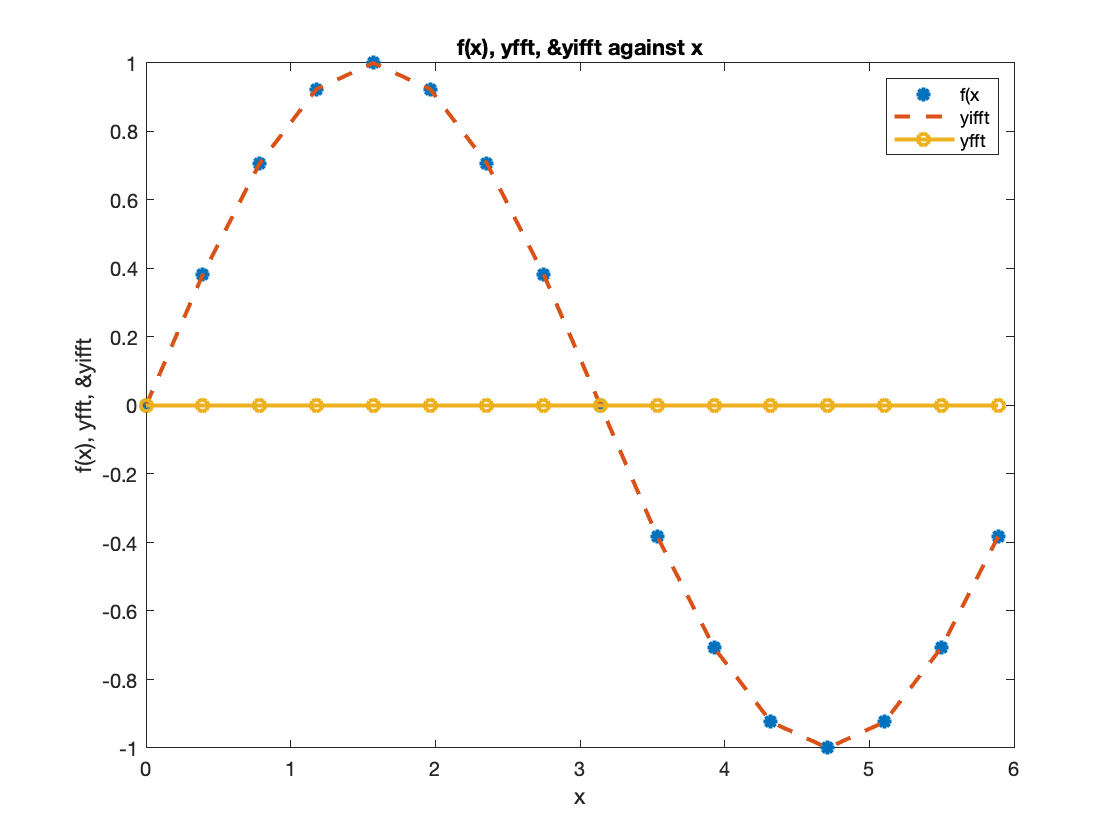

xlabel('x'); ylabel('f(x), yfft, &yifft');
title('f(x), yfft, &yifft against x');
legend('f(x','yifft','yfft');

## Example: Compute the fft of f(x) = cos(2x) + sin(5x) at 16 points

%function f(x)
f = @ (x) cos(2*x) + sin(5*x);
f(x);

%fft of f(x)
y = fft(f(x));

%ifft of f(x) 
yifft = ifft(y);

%plotting
figure(2)
plot(x,f(x),'*','LineWidth',2); hold on
plot(x,yifft,'--','LineWidth',2); hold on
plot(x,y,'-o','LineWidth',2); 

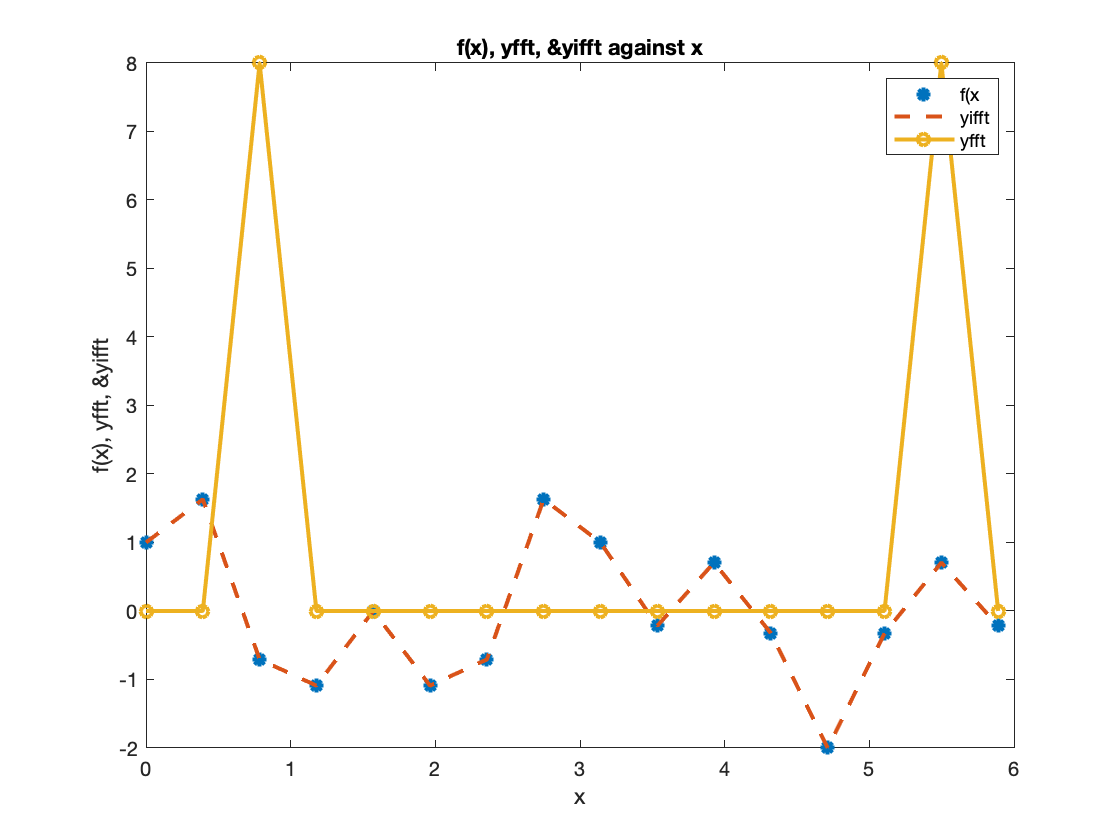

xlabel('x'); ylabel('f(x), yfft, &yifft');
title('f(x), yfft, &yifft against x');
legend('f(x','yifft','yfft');

## fftshift

It shifts zero-frequency components to center of spectrum.

## Usage, y = fftshift(x)

This rearranges a Fourier transform X by shifting the zero-frequency component to the center of the array.

- If x is a vector, then fftshift swaps the left and the right halves of x.

- If X is a matrix, then fftshift swaps the first quadrant of x with the third, and the second quadrant with the fourth.

- If x is a multidimenssional array, then fftshift swaps half-spaces of x along each dimension.

## Usage, y = fftshift(x,dim)

This operates along the dimension, dim, of x. e.g, if x is a matrix whose rows represent  multiple 1-D transforms, then fftshift(x,2) swaps the halves of each row of x.

## Examples

%for x a vector
x

x =          0    0.3927    0.7854    1.1781    1.5708    1.9635    2.3562    2.7489    3.1416    3.5343    3.9270    4.3197    4.7124    5.1051    5.4978    5.8905


y = fftshift(x)

y =     3.1416    3.5343    3.9270    4.3197    4.7124    5.1051    5.4978    5.8905         0    0.3927    0.7854    1.1781    1.5708    1.9635    2.3562    2.7489


y = fftshift(x,2)

y =     3.1416    3.5343    3.9270    4.3197    4.7124    5.1051    5.4978    5.8905         0    0.3927    0.7854    1.1781    1.5708    1.9635    2.3562    2.7489



% for x a Matrix
% when x is a matrix
xmat = [1 2 3 4; 5 6 7 8; 9 10 2 3; 4 3 6 0]

xmat =      1     2     3     4
     5     6     7     8
     9    10     2     3
     4     3     6     0


y = fftshift(xmat)

y =      2     3     9    10
     6     0     4     3
     3     4     1     2
     7     8     5     6


y = fftshift(xmat,2)

y =      3     4     1     2
     7     8     5     6
     2     3     9    10
     6     0     4     3


## Example: Compute the fftshift of f(x) = cos(2x) + sin(5x) at 16 points

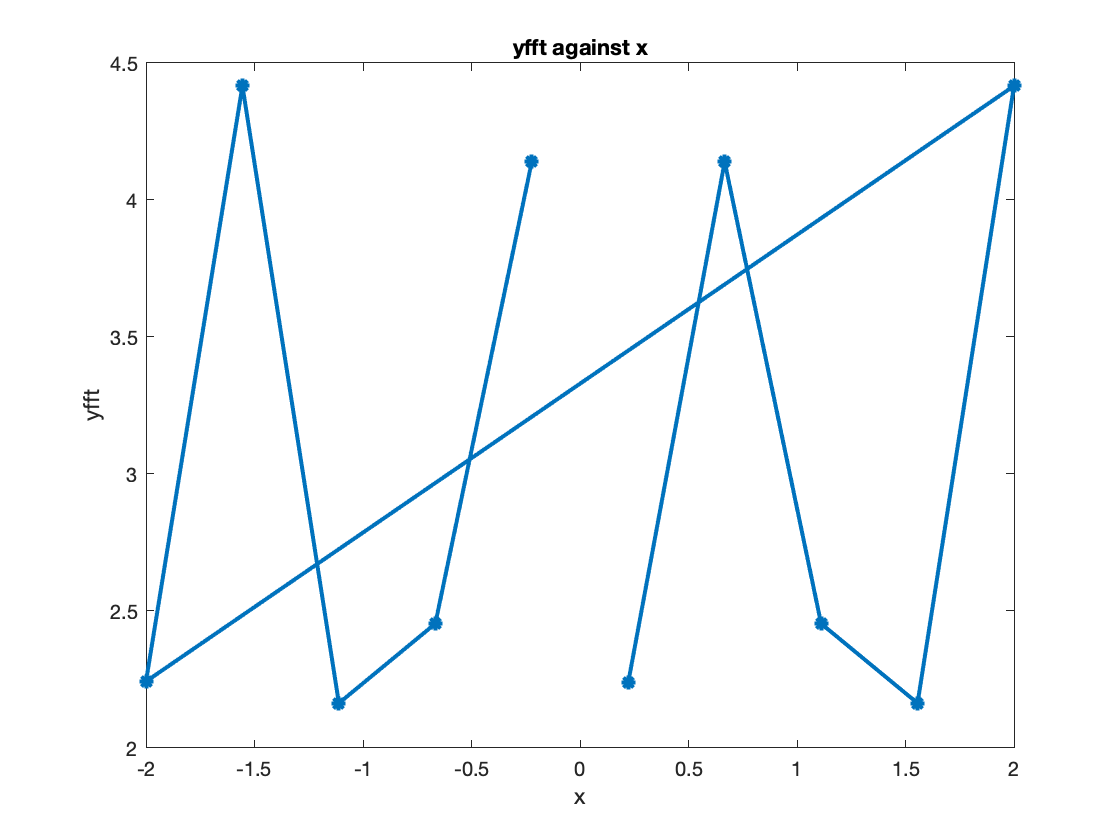

a = -2; b = 2;
n = 10;

%n sample points
x = linspace(a,b,n);
%function f(x)
f = @ (x) cos(2*x) + sin(5*x);
f(x);

%fft of f(x)
y = fft(f(x));

%fftshift
y = fftshift(y);
x = fftshift(x);

%plotting
figure(3)
plot(x,abs(y),'-*','LineWidth',2); 
xlabel('x'); ylabel('yfft');
title('yfft against x');